# Starter code (2-class classifier: cats vs. dogs)

Prof. Oge Marques, PhD - (C) 2020-2022

% Inspired by the example "Deep Learning for Pet Classification" 
% (Copyright 2016 The MathWorks, Inc.)

## Part 1: Load and inspect Pre-trained Convolutional Neural Network (CNN)

## 1.1: Loading a pre-trained "AlexNet"

% Ensure that you have downloaded and installed the 
% "Deep Learning Toolbox Model for AlexNet Network" support package. 

% See https://www.mathworks.com/matlabcentral/fileexchange/59133-deep-learning-toolbox-model-for-alexnet-network
% and
% https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html
% for additional information.

model1 = alexnet;

## 1.2: Inspect the CNN's layers

model1.Layers

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0


% The intermediate layers make up the bulk of the CNN. These are a series
% of convolutional layers, interspersed with rectified linear units (ReLU)
% and max-pooling layers [2]. Following the these layers are 3
% fully-connected layers.

% The final layer is the classification layer and its properties depend on
% the classification task. In this example, the CNN model that was loaded
% was trained to solve a 1000-way classification problem. Thus the
% classification layer has 1000 classes from the ImageNet dataset. 

% Inspect the last layer
model1.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'



% Number of class names for ImageNet classification task
numel(model1.Layers(end).ClassNames)

ans = 1000


% Note that the CNN model is not going to be used for the original
% classification task. It is going to be re-purposed to solve a different
% classification task on the pets dataset.

## Part 2: Set up image data

## 2.1: Load simplified dataset and build image store

dataFolder = '/Users/uwaiseibna/Downloads/cats_vs_dogs/data/PetImages';
categories = {'cat', 'dog'};
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');
tbl = countEachLabel(imds);
disp (tbl)

    Label    Count
    _____    _____

     cat      20  
     dog      20  




% Use the smallest overlap set
% (useful when the two classes have different number of elements but not
% needed in this case)
minSetCount = min(tbl{:,2});

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      20  
     dog      20  


## 2.2: Pre-process Images For CNN

AlexNet can only process RGB images that are 227-by-227. To avoid re-saving all the images to this format, setup the `imds` read function, `imds.ReadFcn`, to pre-process images on-the-fly. The `imds.ReadFcn` is called every time an image is read from the `ImageDatastore`.

Set the ImageDatastore ReadFcn

imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

## 2.3: Divide data into training and validation sets

[trainingSet, validationSet] = splitEachLabel(imds, 0.7, 'randomized');

countEachLabel(trainingSet)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      14  
     dog      14  


countEachLabel(validationSet)

ans = 2×2 table
    Label    Count
    _____    _____

     cat       6  
     dog       6  


## Part 3: Transfer Learning

% The convolutional layers of the network extract image features that the 
% last learnable layer and the final classification layer use to classify 
% the input image. 

% To retrain a pretrained network to classify new images, we must replace these 
% last layers with new layers adapted to the new data set.

## 3.1: Freeze all but last three layers

layersTransfer = model1.Layers(1:end-3);
numClasses = 2; % cat and dog

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## 3.2: Configure training options

options = trainingOptions('adam', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

## 3.3: Retrain network

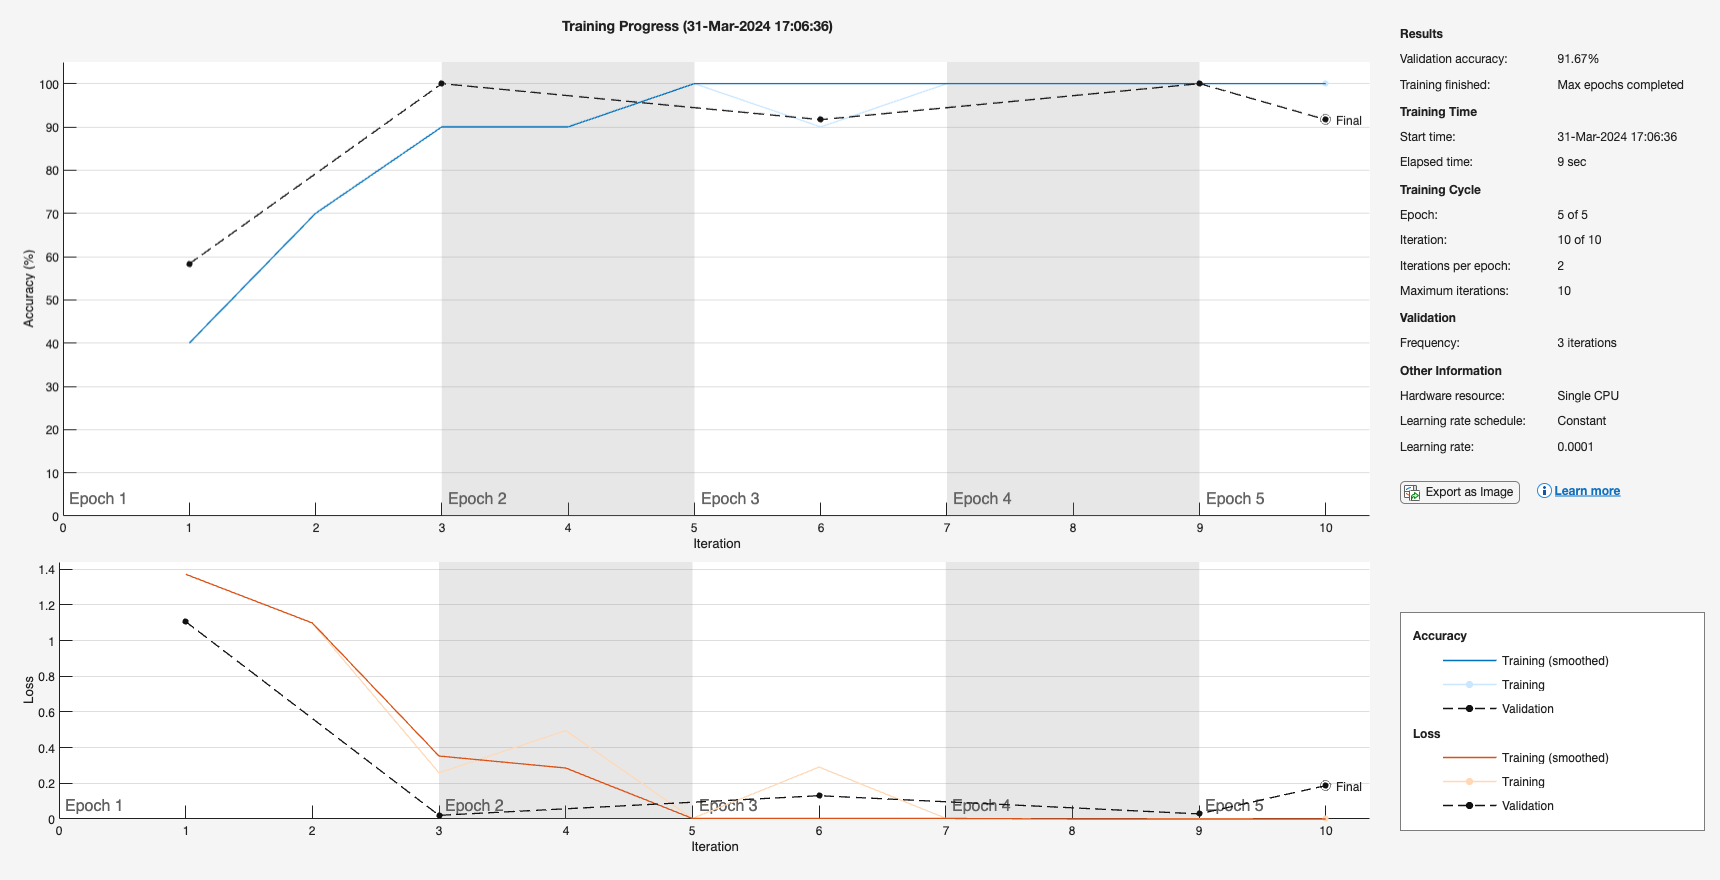

model2 = trainNetwork(trainingSet,layers,options);


% modelTransfer = trainNetwork(trainingSet, layerGraph(model),options); % for squeezenet

## 3.4: Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(model2,validationSet);

## 3.5: Calculate the classification accuracy on the validation set.

Accuracy is the fraction of labels that the network predicts correctly.

YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 91.67 %


## 3.6: Test it on unseen images

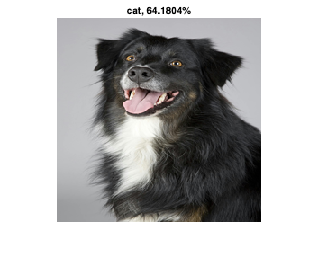

newImage1 = '/Users/uwaiseibna/Downloads/pexels-pixabay-220938.jpg'; % any dog image should do!
img1 = readAndPreprocessImage(newImage1);
YPred1 = predict(model2,img1);
[confidence1,idx1] = max(YPred1);
label1 = categories{idx1};
% Display test image and assigned label
figure
imshow(img1)
title(string(label1) + ", " + num2str(100*confidence1) + "%");

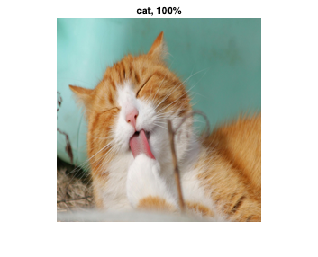


newImage2 = '/Users/uwaiseibna/Downloads/pexels-pixabay-57416.jpg'; % any cat image should do!
img2 = readAndPreprocessImage(newImage2);
YPred2 = predict(model2,img2);
[confidence2,idx2] = max(YPred2);
label2 = categories{idx2};
% Display test image and assigned label
figure
imshow(img2)
title(string(label2) + ", " + num2str(100*confidence2) + "%");

## 3.7: Test it on unseen images: Your turn!

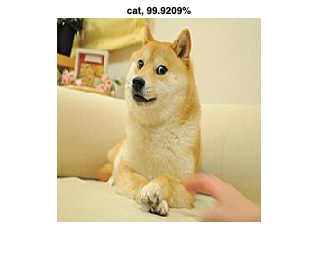

% What about the iconic "Doge"?
% ENTER YOUR CODE HERE
% ..
% ..
newImage3 = '/Users/uwaiseibna/Downloads/doge.jpg'; 
img3 = readAndPreprocessImage(newImage3);
YPred1 = predict(model2,img3);
[confidence1,idx1] = max(YPred1);
label1 = categories{idx1};
figure
imshow(img3)
title(string(label1) + ", " + num2str(100*confidence1) + "%");

## Part 4: Data augmentation

% Data augmentation helps prevent the network from overfitting and
% memorizing the exact details of the training images.

% In MATLAB, this can be done using the "Augmented Image Datastore"
% (https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html)

% Despite its name, however, it DOES NOT increase the actual number of
% samples. When you use an augmented image datastore as a source of
% training images, the datastore randomly perturbs the training data for
% each epoch, so that each epoch uses a slightly different data set. The
% actual number of training images at each epoch does not change. The
% transformed images are not stored in memory.

## 4.1: Defining the imageAugmenter object

In our case, we shall use an augmented image datastore to randomly flip the training images along the vertical axis and randomly translate them up to 30 pixels and scale them up to 10% horizontally and vertically.

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

## 4.2: Building the augmented training and validation sets

inputSize = model1.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations) % You should see 28

    28




augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

disp(augimdsValidation.NumObservations) % You should see 12

    12



## 4.3: Train the network with augmented datasets

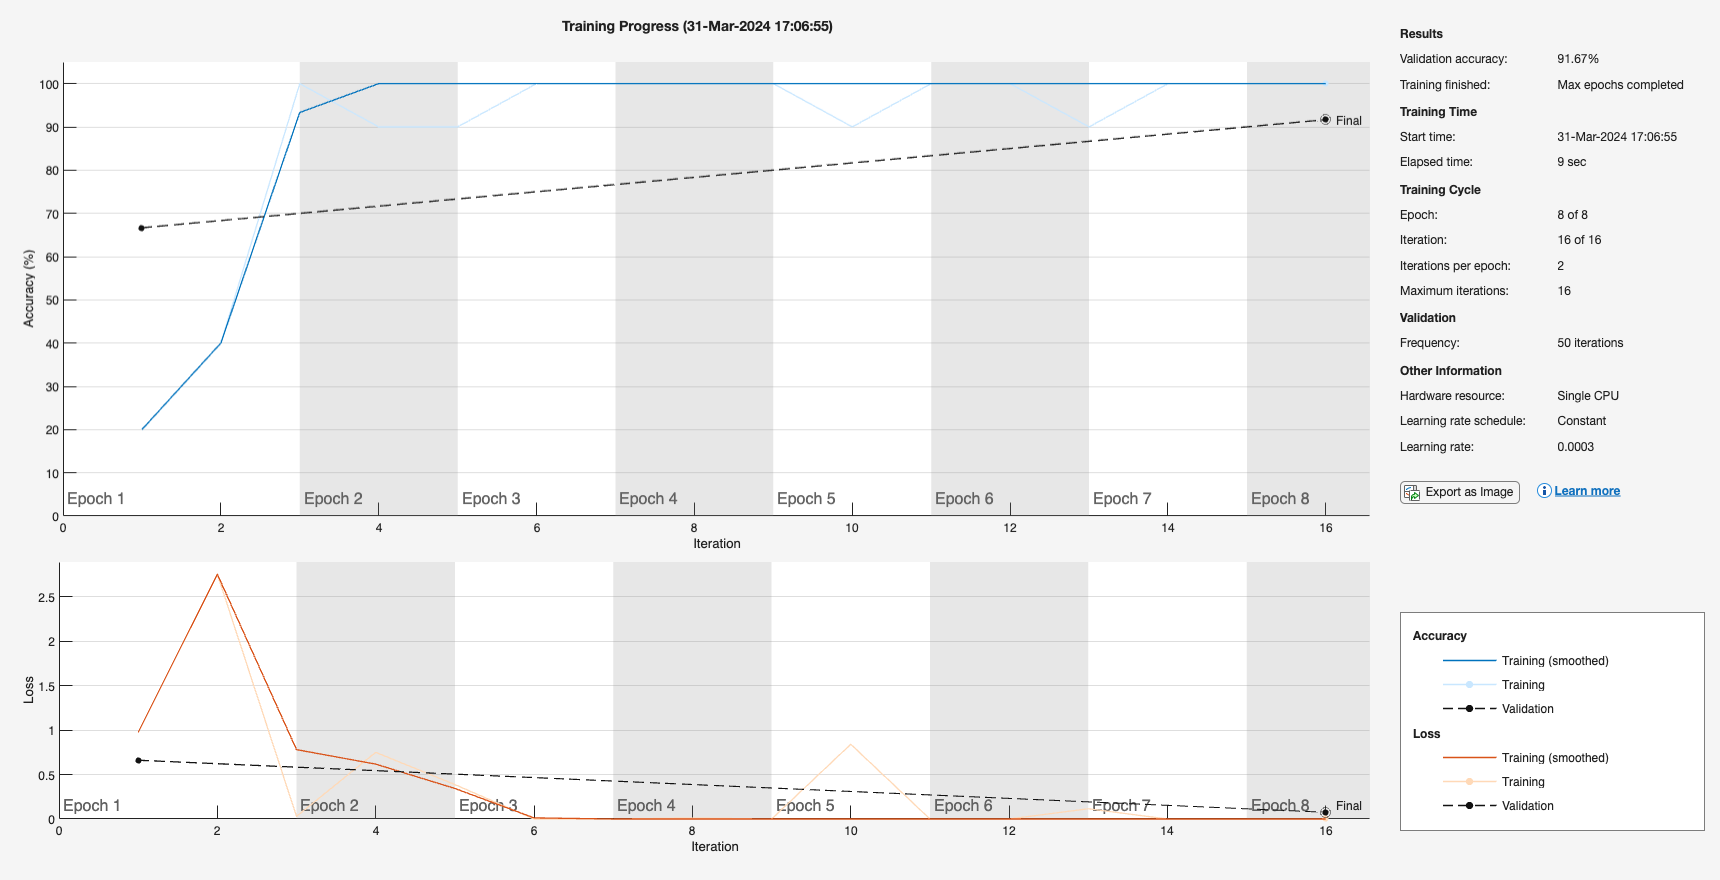

miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

model3 = trainNetwork(augimdsTrain,layers,options);

## 4.4: Classify the validation images using the fine-tuned network.

[YPredAug,probsAug] = classify(model3,augimdsValidation);

## 4.5: Calculate the classification accuracy on the validation set.

Accuracy is the fraction of labels that the network predicts correctly.

YValidationAug = validationSet.Labels;
accuracyAug = mean(YPredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug * 100);

The validation accuracy is: 91.67 %


## Part 5: Larger datasets

path='/Users/uwaiseibna/Downloads/train'

path = '/Users/uwaiseibna/Downloads/train'

categories = {'cat', 'dog'};
imds = imageDatastore(fullfile(path, categories), 'LabelSource', 'foldernames');
tbl = countEachLabel(imds);
disp (tbl)

    Label    Count
    _____    _____

     cat     1000 
     dog     1000 



% Model 1 running different optimizers, learning rates, epochs, and batch
% sizes for alexnet without image augmentation

% Set up parallel pool
parpool('local', 8);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 8 workers.


miniBatchSizes = [30, 40];
maxEpochs = [4, 6];
initialLearnRates = [1e-4, 5e-4];
optimizers = {'adam', 'sgdm'};

imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

[imdsTrain, imdsValidation, imdsTest] = splitEachLabel(imds, 0.6, 0.2, 'randomized');

parfor opt = 1:numel(optimizers)
    optimizer = optimizers{opt};
    
    for i = 1:numel(miniBatchSizes)
        for j = 1:numel(maxEpochs)
            for k = 1:numel(initialLearnRates)
                options = trainingOptions(optimizer, ...
                    'Shuffle','every-epoch', ...
                    'ValidationData',imdsValidation, ...
                    'ValidationFrequency',20, ...
                    'Verbose',false, ...
                    'Plots','training-progress');

                options.MiniBatchSize = miniBatchSizes(i);
                options.MaxEpochs = maxEpochs(j);
                options.InitialLearnRate = initialLearnRates(k);

                model = trainNetwork(imdsTrain, layers, options);

                [YPred, scores] = classify(model, imdsTest);
                YTest = imdsTest.Labels;

                accuracy = mean(YPred == YTest);
                fprintf("For optimizer %s, MiniBatchSize = %d, MaxEpochs = %d, InitialLearnRate = %.1e, the test accuracy is: %.2f %%\n", ...
                    optimizer, miniBatchSizes(i), maxEpochs(j), initialLearnRates(k), accuracy * 100);

                % Display confusion matrix
                cm = confusionmat(YTest, YPred);
                disp(cm);
            end
        end
    end
end

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 1.0e-04, the test accuracy is: 96.25 %
   192     8
     7   193

For optimizer adam, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 1.0e-04, the test accuracy is: 90.00 %
   195     5
    35   165

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 5.0e-04, the test accuracy is: 89.75 %
   173    27
    14   186

For optimizer adam, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 5.0e-04, the test accuracy is: 56.75 %
    35   165
     8   192

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 6, InitialLearnRate = 1.0e-04, the test accuracy is: 95.50 %
   188    12
     6   194

For optimizer adam, MiniBatchSize = 30, MaxEpochs = 6, InitialLearnRate = 1.0e-04, the test accuracy is: 94.75 %
   191     9
    12   188

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 6, InitialLearnRate = 5.0e-04, the test accuracy is: 90.75 %
   184    16
    21   179

For optimizer adam, 


% Close parallel pool
delete(gcp);

Parallel pool using the 'Processes' profile is shutting down.


% Best Model-> For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 1.0e-04, the test accuracy is: 96.25 %

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 8 workers.
Parallel pool using the 'Threads' profile is shutting down.


%confusion matrix
% cat   192     8
% dog     7   193

% Model 1 running different optimizers, learning rates, epochs, and batch
% sizes for alexnet with image augmentation

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 8 workers.
Parallel pool using the 'Threads' profile is shutting down.


inputSize = model.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations)

        1200



augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

disp(augimdsValidation.NumObservations) % You should see 12

   400



augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

disp(augimdsTest.NumObservations)

   400



% Set up parallel pool
parpool('local', 8);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to parallel pool with 8 workers.


miniBatchSizes = [30, 40];
maxEpochs = [4, 6];
initialLearnRates = [1e-4, 5e-4];
optimizers = {'adam', 'sgdm'};


parfor opt = 1:numel(optimizers)
    optimizer = optimizers{opt};
    
    for i = 1:numel(miniBatchSizes)
        for j = 1:numel(maxEpochs)
            for k = 1:numel(initialLearnRates)
                options = trainingOptions(optimizer, ...
                    'Shuffle','every-epoch', ...
                    'ValidationData',augimdsValidation, ...
                    'ValidationFrequency',20, ...
                    'Verbose',false, ...
                    'Plots','training-progress');

                options.MiniBatchSize = miniBatchSizes(i);
                options.MaxEpochs = maxEpochs(j);
                options.InitialLearnRate = initialLearnRates(k);

                model = trainNetwork(augimdsTrain, layers, options);

                [YPred, scores] = classify(model, augimdsTest);
                YTest = imdsTest.Labels;

                accuracy = mean(YPred == YTest);
                fprintf("For optimizer %s, MiniBatchSize = %d, MaxEpochs = %d, InitialLearnRate = %.1e, the test accuracy is: %.2f %%\n", ...
                    optimizer, miniBatchSizes(i), maxEpochs(j), initialLearnRates(k), accuracy * 100);

                % Display confusion matrix
                cm = confusionmat(YTest, YPred);
                disp(cm);
            end
        end
    end
end

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 1.0e-04, the test accuracy is: 94.25 %
   191     9
    14   186

For optimizer adam, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 1.0e-04, the test accuracy is: 92.75 %
   172    28
     1   199

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 5.0e-04, the test accuracy is: 86.25 %
   179    21
    34   166

For optimizer adam, MiniBatchSize = 30, MaxEpochs = 4, InitialLearnRate = 5.0e-04, the test accuracy is: 63.25 %
    89   111
    36   164

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 6, InitialLearnRate = 1.0e-04, the test accuracy is: 96.00 %
   190    10
     6   194

For optimizer adam, MiniBatchSize = 30, MaxEpochs = 6, InitialLearnRate = 1.0e-04, the test accuracy is: 88.50 %
   154    46
     0   200

For optimizer sgdm, MiniBatchSize = 30, MaxEpochs = 6, InitialLearnRate = 5.0e-04, the test accuracy is: 92.75 %
   185    15
    14   186

For optimizer adam, 


% Close parallel pool
delete(gcp);

Parallel pool using the 'Processes' profile is shutting down.


% best model optimizer adam, MiniBatchSize = 40, MaxEpochs = 4, InitialLearnRate = 1.0e-04, the test accuracy is: 96.75 %
%confusion matrix
% cat 193     7
% dog  6   194
